# ***patchclamp *****documentation**

**Version 02/20/22**

**Niraj S. Desai**

**niraj.s.desai@gmail.com**

This is a first draft of documentation for *patchclamp*, a data acquisition program for cellular neurophysiology (see [https://github.com/nsdesai/patchclamp)](https://github.com/nsdesai/patchclamp)). The program itself is still under revision and this document will certainly be revised, but it gives a good idea of how the program is structured -- including its fundamental logic -- and how to use it.

Please direct any questions or comments to me (NSD) at niraj.s.desai@gmail.com.

## Requirements

- **Windows. **A Windows computer is required because the software makes use of Matlab's Data Acquisition Toolbox, which is available for Windows operating systems only. *patchclamp* has been successfully tested on both Windows 10 and Windows 11 systems.

- **Patch clamp amplifier.** The program was written with the Multiclamp 700A and 700B patch clamp amplifiers in mind, but it can, in principle, be used with any amplifier. However, computer control is available only for Multiclamp amplifiers. Soon I will add additional support to read the telegraph outputs of the Axopatch 200B, but full control is limited to the Multiclamp models because (a) many existing amplifiers, including the Axopatch 200B, cannot be computer controlled and (b) I don't have access to the other amplifiers that can.

- **Data acquisition device.** The program was written with National Instruments devices in mind, but any device supported by Matlab's Data Acquisition Toolbox should work. A list of supported devices is available here: [https://www.mathworks.com/hardware-support/data-acquistion-software.html.](https://www.mathworks.com/hardware-support/data-acquistion-software.html.)

- **MATLAB.** The program requires Matlab and its Data Acquisition Toolbox. Any Matlab version more recent than Matlab 2018a should work, but I recommend Matlab 2021a or later. The Mathworks significantly improved the graphics capabilities of its App Designer feature with that release.

## Installation

### Software

- Install your patch clamp amplifier and data acquisition device according to the manufacturers' instructions. For example, (1) attach a Multiclamp 700B amplifier to your computer using a USB cable and then download and install the Multiclamp Commander software from the Molecular Devices website: [https://support.moleculardevices.com/s/article/Axon-MultiClamp-700B-Commander-Download-page](https://support.moleculardevices.com/s/article/Axon-MultiClamp-700B-Commander-Download-page) and (2) place a National Instruments PCIe card in your computer and download and install the NI-DAQmx software from the National Instruments website: [https://www.ni.com/en-us/support/downloads/drivers/download.ni-daqmx.html#428058](https://www.ni.com/en-us/support/downloads/drivers/download.ni-daqmx.html#428058).

- Download and install Visual Studio Community 2019 from Microsoft: [https://docs.microsoft.com/en-us/visualstudio/releases/2019/release-notes.](https://docs.microsoft.com/en-us/visualstudio/releases/2019/release-notes.) During the installation, select all the options related to C++ programming. (If you are unsure of what to select, just write to me.) This step is necessary because, to control Multiclamp amplifiers, I wrote a separate program as a Visual Studio C++ project; the Matlab program *patchclamp* communicates with the amplifiers through this C++ program. Do not install Visual Community 2022 instead of 2019. While 2022 is the newest version of Microsoft's community offering, at this writing (February 2022) most community software, including Matlab, are not ready to use it.

- Download and install Matlab and its Data Acquisition Toolbox. (If you work at NINDS, you can do so through NINDS IT, as we have a site license.)

- Within Matlab, open the Add-On Explorer (look for "Add-Ons" on the toolbar at the top, look on the right). Find and install the Data Acquisition Toolbox Support Package for National Instruments NI-DAQmx Devices.

- Download the *patchclamp *folder from [https://github.com/nsdesai/patchclamp](https://github.com/nsdesai/patchclamp) and put it in the Matlab folder within the Documents folder. 

- Add the folder to the Matlab search path. You can do this in multiple ways. One way: with the Matlab folder as the current directory, type the following lines at the Matlab command line:

addpath('patchclamp')
savepath

- Finally, connect the amplifier and the data acquisition (DAQ) device with BNC cables. How you do this is up to you but a sensible arrangement is to connect the first output channels of the amplifier (called "Scaled Output" in the case of Multiclamp amplifiers) to the first input channels of the DAQ device (called "ai0", "ai1", and so on in the case of National Instruments devices). Likewise, connect the first input channels of the amplifier (called "Command Input" in the case of the Multiclamp amplifiers) to the first output channels of the DAQ device (called "ao0", "ao1", and so on in the case of National Instruments devices). If you're planning to use the National Instruments digital outputs to trigger electrical or optogenetic stimulation, connect those too. For example, connect the first digital outputs (called "port0/line0","port0/line1", and the like in the case of National Instruments devices) to the target stimulation devices, such as an IsoFlex stimulus isolation unit or an LED optostimulation unit.

### Specifying connections

The first time you open *patchclamp* is special in that you need to start by telling the program what is connected to it. That is to say: what is the patch clamp amplifier? what is the data acquisition device? what channels are connected to what?

To answer these questions, start by first turning on any amplifiers you have, and then opening the *patchclamp* program by typing "patchclamp" at the Matlab command line; this will open up the main *patchclamp* graphical user interface (GUI). (It is important that you turn on the amplifiers before opening the *patchclamp *program because the program searches for connected amplifers at startup.)

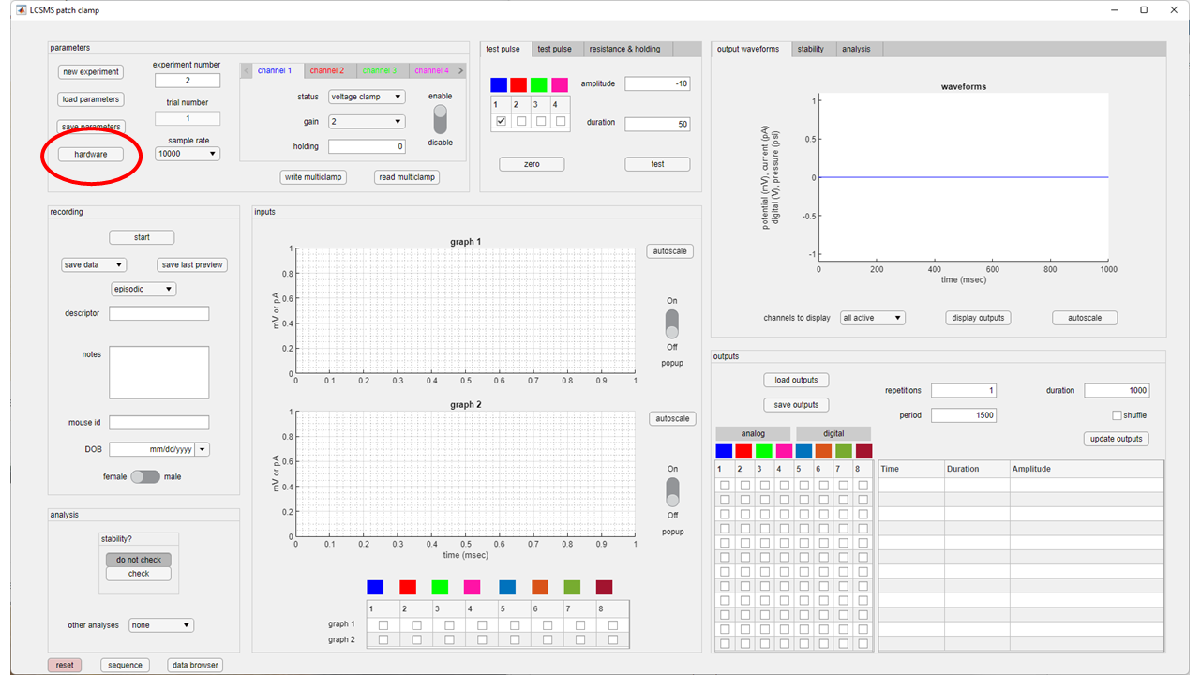

At upper left (circled in red) is a button called "hardware". Push it.

Doing so opens up a different GUI, one also called "hardware".

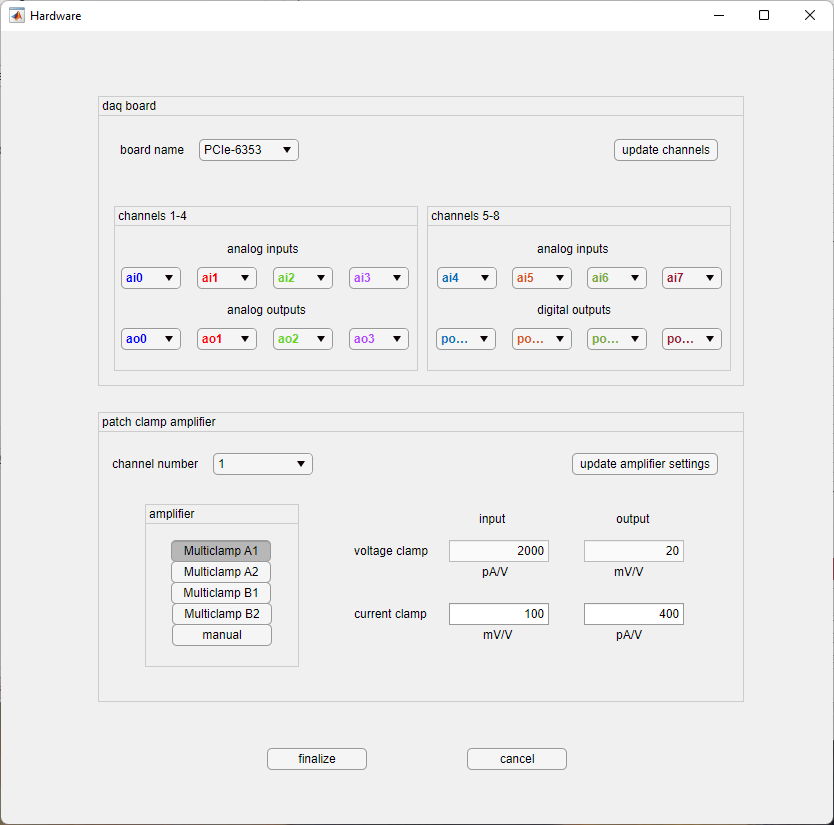

The top panel specifies the connections of the DAQ board. (In this example, it is a PCIe-6353 from National Instruments). The bottom panel specifies the connections of the patch clamp amplifier. (In this case, two Multiclamp amplifiers are installed). The entries will come pre-populated with the most likely connections, but one can make selections for both DAQ board and patch clamp amplifier through this GUI.

**Top panel.** The program is set up to handle up to eight (8) channels. The first four (channels 1-4) are meant for patch clamp connections. Each connection includes both an input and an output. In the case of a Multiclamp 700B, the input specifies which DAQ analog input receives a signal from the "Scaled Output" of the Multiclamp, and the output specifies which DAQ analog output sends a signal to the "Command Input" of the Multiclamp. In the example above, a Multiclamp 700B is using the National Instruments board's first analog input (ai0) to read its scaled output and its first analog output (ao0) to send it commands (e.g., a current injection or a holding potential).

The second four (channels 5-8) are meant for digital connections (i.e., triggers for stimulus isolation unit, LED light, picospritzer). These triggers are sent by the National Instrument board's digital outputs, which have names like port0/line0, port0/line1, and so on. These channels can also be used to record analog inputs from sources other than a patch clamp amplifier, such as an extracellular amplifier for field potentials or a pressure monitor. In this example, National Instruments analog inputs ai4, ai5, ai6, and ai7 are used in this way.

After making changes to these assignments, press the button *update channels *to cofirm your changes.

**Bottom panel.** Each of the four patch clamp channels can be selected through the dropdown menu *channel number*. The toggle buttons allow you to assign a given patch clamp channel to one channel of a Multiclamp amplifier (each of these amplifiers has two channels) or to specify a "manual" amplifier (i.e., one not controlled by *patchclamp*). 

In the case of Multiclamp amplifiers, the program will query the amplifiers and determine the correct scaling for current clamp and voltage clamp recordings. For example, when the amplifier is in current clamp, it signals the membrane potential (*Vm*) through a voltage signal sent out of its Scaled Output BNC. The signal will be a voltage equal to *gain* * *Vm* / (100 mV/V), where *gain *is the gain a user specifies in the Multiclamp Commander window. If you specifed a *gain *of 10 in the Commander and the neuron is sitting at *Vm* = -65 mV, then the signal coming out of Scaled Output will be 10 * -65 / 100 = -6.5 V.

Different amplifiers have different scalings. The Multiclamp 700A's current clamp setting, for example, differs from that of the Multiclamp 700B by a factor of 10. If you use an amplifier other than a Multiclamp (or, as soon as I write the revisions, an Axopatch 200B), then you need to know your amplifier's scalings and enter them into this GUI. (In some cases, the scalings will be written on the amplifer itself, next to the corresponding BNC port.)

After making changes to these assignments, press the button *update amplifier settings *to confirm your changes.

Finally, press the button *finalize* at the bottom to save all changes and close the *hardware* GUI. The hardware configuration will be saved in the file hardwardConfiguration.mat, which may be found inside the folder patchclamp > parameters_and_gui. Anytime after this, when you open *patchclamp*, the program will load this configuration and use it. If you don't add an amplifier or change what is connected to what, you shouldn't need to use the *hardware* GUI again.

## The Graphical User Interface (GUI)

The program works through the main graphical user interface (GUI). It is important to familiarize yourself with its parts. Turn on the patch clamp amplifiers and then open the GUI by typing "patchclamp" at the Matlab command line. (If you reverse the order, the program will complain that it cannot find the amplifiers. In that case, turn on the amplifiers and type "patchclamp" again. It should be fine.)

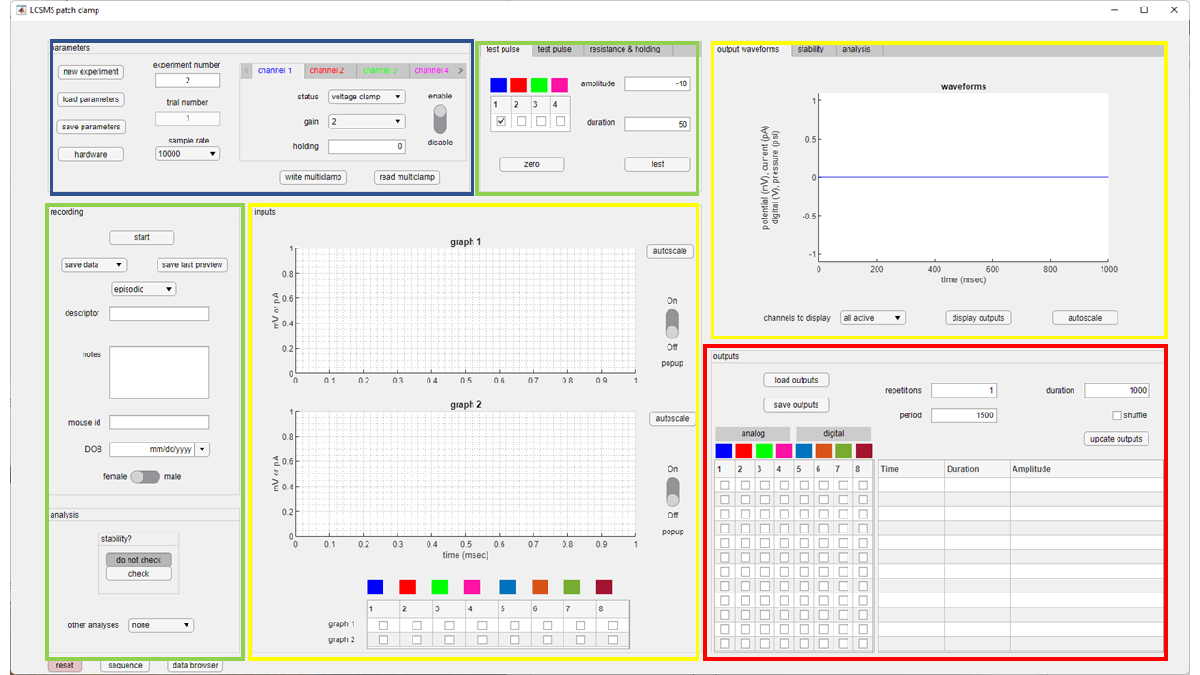

As illustrated, the GUI is divided into four main areas: (1) parameters, blue box; (2) outputs (a.k.a. stimuli or protocols), red box; (3) controls, green boxes (one is at left, one is at upper middle); and (4) displays, yellow boxes. These are fundamental categories in all types of data acquisition, and it is useful to go through them in some detail to understand the logic of the program and how to navigate the GUI.

### Parameters

The section of the GUI at upper left deals with "parameters". In specifying parameters, one specifies things like (a) is the recording being done in current clamp or voltage clamp or I=0 or field potential mode or something else?, (b) what are the gain and the holding potential (voltage clamp) or holding current (current clamp) of the recording?, (c) what are the experiment and trial numbers?, (d) what is the sample rate?

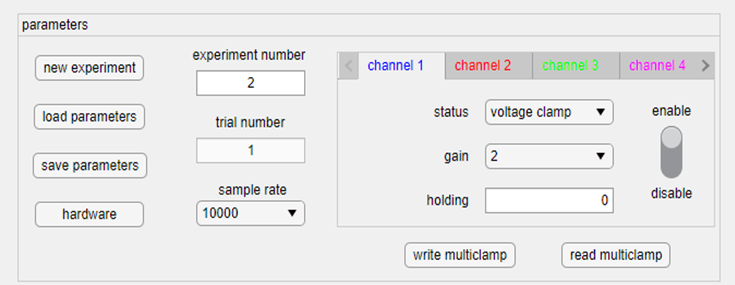

*Experiment.* In the program's nomenclature, each individual recording configuration is called an "experiment". If you record from one neuron and subject it to a variety of stimuli, that is one experiment. If you then record from two other neurons simultaneously abnd subject them to a different set of stimuli, that is a second experiment. Some programs would label these different sets of data by the term "cell", but since each recording configuration might include multiple cells or might record an extracellular potential or some other non-intracellular recording, I favor the term "experiment". So, if you record from 10 cells on a (very good) recording day, the data will be grouped into experiments 1 through 10. 

*Trial. *Within each experiment, you will likely do multiple, separate things: inject a family of current steps, attempt to induce LTP, inject a second set of current steps, record mEPSCs in voltage clamp, and so on. Each of these individual recordings are called "trials" by the program. (Other programs might call them "sweeps" instead -- same thing.) 

When you open the GUI for the first time on a recording day, *experiment number *will be 1 and *trial number *will be 1. After you get the first cell (or cells) and collect the first bit of data, the data will be specified by experiment001trial001 and *trial number *will be incremented by 1, meaning that the next bit of data will be specified by expeirment001trial002. As you keep collecting data, the trial number will keep incrementing. When you are done with the first cell and want to get a new one, press the button *new experiment*. This will advance *experiment number *to 2 and reset *trial number* to 1. Both the *experiment number *and *trial number* fields are editable, meaning that, if you press *new experiment* by mistake, you can manually change *experiment number *and *trial number *back to the previous values. A caveat: with great power comes great responsibility: if you manually change the experiment and trial numbers, you should be careful that you're not overwriting data you want to keep.

*Sample rate.* The dropdown menu *sample rate* allows you to specify the sample rate of data acquisition. The default is 10 kHz, which is fine for most patch clamp-type things. Some exceptions: voltage clamping a sodium current or measuring a calcium tail current requires a much higher sampling rate. The good news: a standard DAQ board, like the PCIe-6353 that the LCSMS uses, can handle rates greater than 1 MHz.

The program is set up to handle acquisition from up to eight (8) channels simultaneously, of which four (channels 1-4) can be patch clamp recordings.(Expanding it to handle more patch clamp recordings is possible but would require purchasing multiple DAQ boards.) What each patch clamp channel is doing is specified by the tab menu on the right-hand side of the above figure. In this example, channel 1 is in voltage clamp with a gain of 2 and a holding potential of 0 mV. It is also enabled. The patch clamp channels each have an enable-disable toggle switch. If the channel will not be in use, toggle it to "disable" so that the program does not keep checking its state to see whether or not to pay attention to it. Using the pulldown menu *status, *one can specify whether the recording on any particular channel will be done in voltage clamp, current clamp, I=0, or field potential mode. The channels can also be off, which means they won't be recorded even if enabled. The channels are all independent of each other: channel 1 can be in voltage clamp, channel 2 in current clamp, channel 3 off, and channel 4 in field potential mode. The pulldown menu *gain* is used to specify the amplifier gain (in the case of Multiclamp amplifiers, this is the number called "Output Gain" in the Multiclamp Commander). The pulldown menu *holding *is used to specify the holding potential (in mV), when the recording is being done in voltage clamp mode, or the holding current (in pA), when the recording is being done in current clamp mode. (In I=0 or field potential mode, the holding value is meaningless.)

The other four channels (channels 5-8) simply record voltages straight (without attempting to convert them to mV or pA). They also send out digital outputs (0 or 1). Whereas the outputs of the patch clamp channels (1-4) are tied to the recording mode (current clamp means pA, voltage clamp means mV), the outputs of the digital channels are always 0 or 1 (physically, given the TTL standard, this means 0 V or 5 V).

*Multiclamp.* The Multiclamp 700A and 700B are different from most other patch clamp amplifiers in that they are almost exclusively computer controlled. In fact, they do not have the BNC telegraph outputs nearly every other amplifier on the market contains. To learn about their status (recording mode, gain, holding potential/current) or to change their status, one needs to interact directly with the software. In general, this is not an easy task. (One of my proudest achievements, pathetically enough, was writing a C++ program to do this [Desai et al., JNeurophysiol. 2015]. I still (in February 2022!) get email from people thanking me for this dumb contribution to the neuroscience community. It's both flattering and ridiculous.) The buttons *write multiclamp *and *read multiclamp* perform the writing and reading functions, respectively. It is important that *patchclamp *and the Multiclamp Commander agree about the status of every channel: voltage clamp or current clamp or I=0? gain? holding? The program *patchclamp* does not query the Multiclamp amplifier all the time because it takes 1.2 sec per channel to do so. So, if you change a channel's status in the *patchclamp *GUI, you should press the button *write multiclamp* to update the Multiclamp Commander on the change. Or if you change the amplifier's status through the Multiclamp Commander, it is important that you then inform *patchclamp* of the change by pressing the button *read multiclamp*. Worst case scenario: if you neglect to do either thing, then when you press the *start *button to take a recording, *patchclamp *will spend about 1.5 sec checking and correcting the discrepancy: not a huge penalty but an annoying one. 

Let's say that you have established settings on all channels for a test you wish to perform (e.g., channel 1 is in voltage clamp, channel 2 is in current clamp, channel 5 is stimulating at 100 Hz, all other channels are off or disabled, the sampling rate is 50 kHz). You can save these settings by pressing the button *save parameters *and using the resulting popup window to specify where the settings file will be saved. The default folder is patchclamp > user_files > parameters.

Later, in the same session or in any subsequent session, if you wish to recall these settings, you can press the button *load parameters*, locate your settings file, and load the settings for use. (It is also possible to use *protocolsequence*, as described below, to recall saved settings automatically.)

### Outputs

Outputs are different from settings. Settings only specify the state of the amplifier channels (voltage clamp or current clamp or I=0, gain, holding). Outputs are the protocols or stimuli that are injected into the channels (which is to say, neurons or stimulation devices). They include current steps and ramps (in current clamp), command potential steps (in voltage clamp), the patterns of triggers sent to stimulus isolation units or LED light sources, and so forth. In other programs, outputs might be called "protocols" or "stimuli". But they're all the same thing.

In *patchclamp*, one specifies an output protocol using the lower right panel of the GUI.

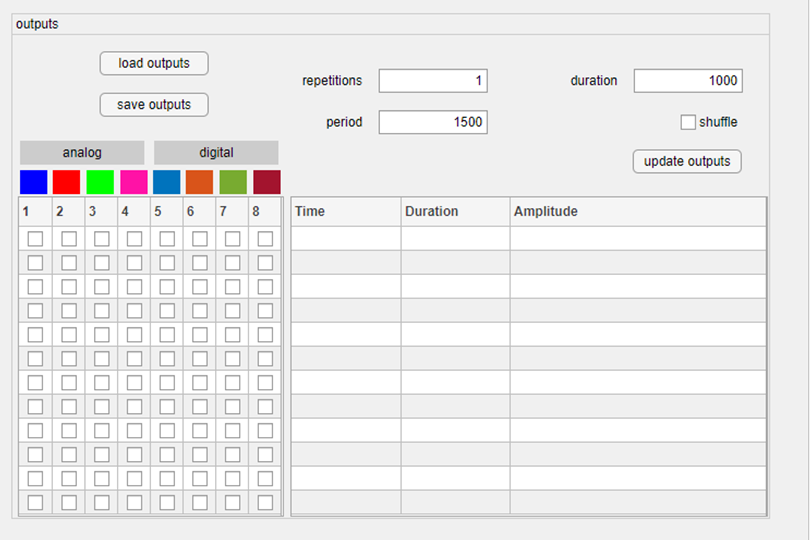

Most data acquisition in *patchclamp *is **EPISODIC. **(A new continuous or gap-free method of recording has recently been added and is described in a subsequent section.) The basic parameters of episodic acquisition are how long each episode of data will be acquired (specified by the field *duration *in msec), how much time will lapse between the start of each episode (specified by the field *period* in msec), and how many times the specified episodes will repeat (specified by the field *repetitions*). If the checkbox *shuffle* is checked, the order of presentation of different episodes will be randomized.

Eight channels of outputs are possible. The first four (analog) are linked to the four patch clamp channels. This means, for example, that if channel 1 is in current clamp and channel 2 is in voltage clamp, the output of the first will be a current in pA whereas the output of the second will be a command potential in mV. The last four (digital) are purely digital outputs -- they can send out 0 V or 5 V.

The outputs panel has 12 lines, which are summed up to form the final output; this allows the user to specify complicated output patterns. Whether a given line applies to a given channel depends upon whether the channel's checkbox for that line is checked or not. 

### Displays (outputs)

### Controls

### Displays (inputs)

#### Popup windows

#### Zooming & panning

#### Data browser

### Real-time analysis

### Sequences & shortcuts

## Acquiring Data

### Starting *patchclamp*

### Getting a gigaohm seal and breaking through

### Fundamentals of acquiring data

### Example 1: a family of current steps

### Example 2: paired-pulse responses with varying time intervals

### Example 3: mEPSC recordings

### Example 4: inducing LTP with TBS

### Example 5: inducing LTP with STDP

### Example 6: probing frequency response with sinusoids & chirps

### Example 7: characterizing a sodium current

### Example 8: feeding synaptic recordings back in current clamp

### Example 9: modeling "in vivo-like" background using Ornstein-Uhlenbeck processes

### Example 10: probing synaptic summation with alpha functions

## Saving Data

## Analyzing and Exporting Data

### *analyzepatch*

### Exporting to CSV

### Exporting to ABF